# polyshape类求多边形交集、并集、周长、面积

[MATLAB | 如何轻易求出多边形交集、并集、周长、面积？polyshape类介绍 (qq.com)](https://mp.weixin.qq.com/s?__biz=Mzg4MTcwODk5Ng==&mid=2247485007&idx=1&sn=e87ab5155acdb2185f024b21412bd600&chksm=cf609ce4f81715f2f1d39ed1b66d592f353482db40f75969e9b26f5e35fb4ff1f81c2ab5f99b&scene=178&cur_album_id=2736083636160020481#rd)

[二维多边形 - MATLAB - MathWorks 中国](https://ww2.mathworks.cn/help/matlab/ref/polyshape.html)

[基础多边形 - MATLAB & Simulink - MathWorks 中国](https://ww2.mathworks.cn/help/matlab/elementary-polygons.html)

## polyshape对象的创建与绘图

polyshape对象可以通过如下方式创建：

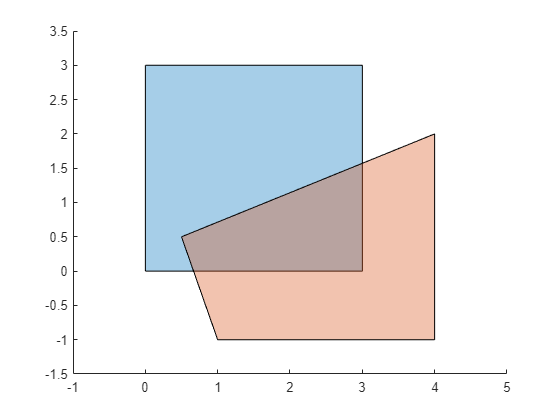


% 创建两个polyshape对象
pgon1=polyshape([0 0 3 3],[3 0 0 3]);
pgon2=polyshape([1/2 1 4 4],[1/2 -1 -1 2]);

% 绘图
figure
plot(pgon1)
hold on
plot(pgon2)

## polyshape对象的布尔运算

intersect     polyshape对象的交集

subtract      两个polyshape对象的差集

union          polyshape对象的并集

xor             两个polyshape对象的异或

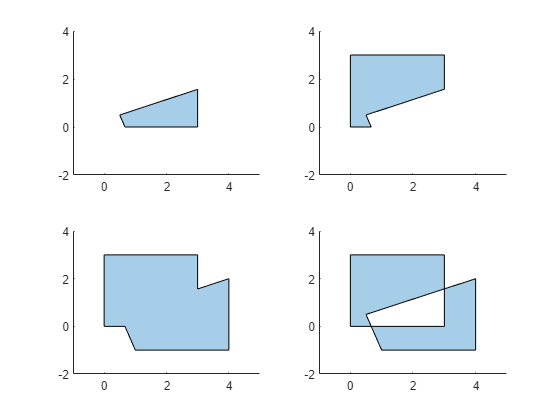

% 创建两个polyshape对象
pgon1=polyshape([0 0 3 3],[3 0 0 3]);
pgon2=polyshape([1/2 1 4 4],[1/2 -1 -1 2]);

figure
% 子图1：交集
subplot(2,2,1);
axis([-1,5,-2,4]);hold on
plot(intersect(pgon1,pgon2))
% 子图2：差集
subplot(2,2,2)
axis([-1,5,-2,4]);hold on
plot(subtract(pgon1,pgon2))
% 子图3：并集
subplot(2,2,3)
axis([-1,5,-2,4]);hold on
plot(union(pgon1,pgon2))
% 子图4：异或
subplot(2,2,4)
axis([-1,5,-2,4]);hold on
plot(xor(pgon1,pgon2))

## polyshape对象的相关信息

值得一提的的是，对于polyshape对象进行的布尔运算和后面对其进行的基本操作的返回值都依旧是polyshape对象，依旧可以用下面所示的方法提取各种相关信息。

例如我们有下面一个取并集得来的多边形：

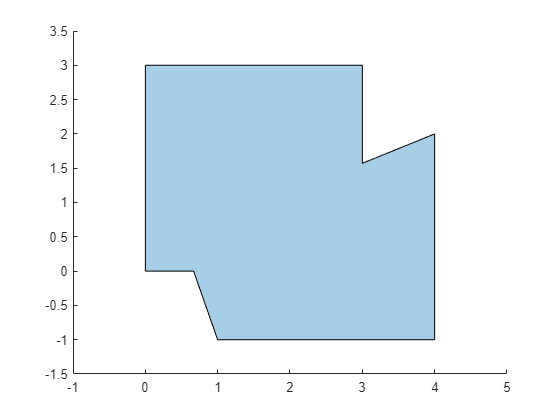

% 创建polyshape对象
pgon1=polyshape([0 0 3 3],[3 0 0 3]);
pgon2=polyshape([1/2 1 4 4],[1/2 -1 -1 2]);
pgon3=union(pgon1,pgon2);
figure
plot(pgon3);

对于不同版本MATLAB，大部分信息都有两种获取方式，例如面积信息可以用：

pgon.area

area(pgon)

两种方式获取。

% 计算面积
disp('');disp('面积为：')

面积为：


disp(pgon3.area)

   13.9524



disp(area(pgon3))

   13.9524




% 计算周长
disp('');disp('周长为：')

周长为：


disp(pgon3.perimeter)

   16.2373



disp(perimeter(pgon3))

   16.2373



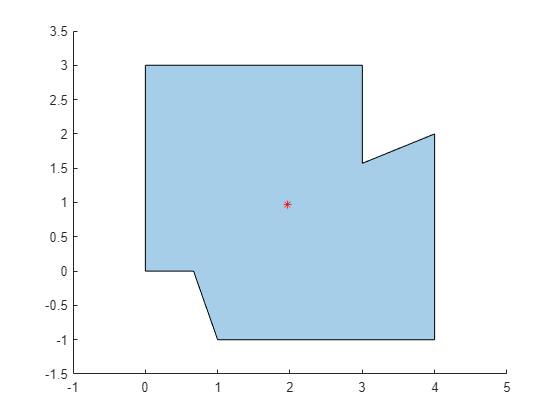


% 计算矩心
[x,y]=centroid(pgon3);
figure
plot(pgon3);
hold on
plot(x,y,'r*')

disp('');disp('矩心为：')

矩心为：


disp([x,y])

    1.9662    0.9709



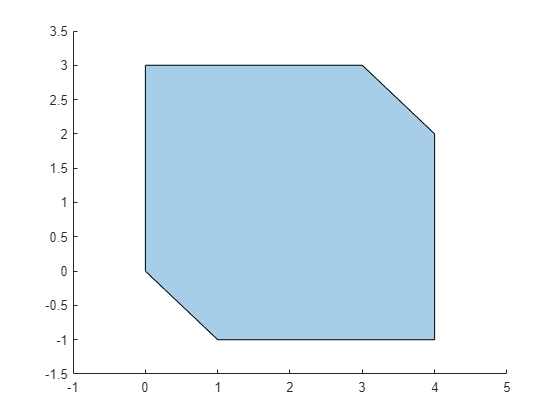


% 计算凸包
polyout=convhull(pgon3);
figure
plot(polyout);

## polyshape对象的操作

rotate            旋转polyshape对象

scale             缩放polyshape对象

translate        平移polyshape对象

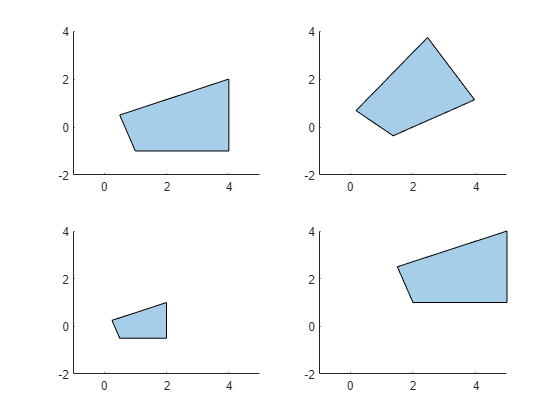

% 创建polyshape对象
pgon=polyshape([1/2 1 4 4],[1/2 -1 -1 2]);

figure
% 子图1：原图
subplot(2,2,1);
axis([-1,5,-2,4]);hold on
plot(pgon)
% 子图2：旋转
subplot(2,2,2)
axis([-1,5,-2,4]);hold on
plot(rotate(pgon,30))
% 子图3：放缩
subplot(2,2,3)
axis([-1,5,-2,4]);hold on
plot(scale(pgon,.5))
% 子图4：平移
subplot(2,2,4)
axis([-1,5,-2,4]);hold on
plot(translate(pgon,[1,2]))